# Demo:  Modeling a 3GPP Antenna Pattern

3GPP has several widely-used antenna model that can be used for simulating designs.  In this demo, we will show how to model this antenna in MATLAB's Antenna Toolbox.  In going throough this demo, you will learn to:

- Model a commercial 3GPP antenna pattern

- Normalize the antenna pattern

- Create a custom antenna object in the Antenna Toolbox with the pattern

- Plot the pattern

- Rotate the patterns

## Creating the Unnormalized Pattern 

We usa common model that can be found in 38.900:

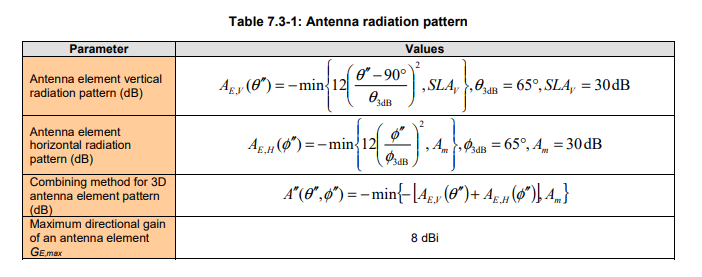

We first enter the parameters.  Just for illustration, we will use a slightly smaller elevation beamwidth.

% Azimuth and elevation half-power beamwidth
azHpbw = 65;  
elHpbw = 45;

% Side-lobe and min gain
SLAv = 30;
Am = 30;

We then create a matrix with the directivity

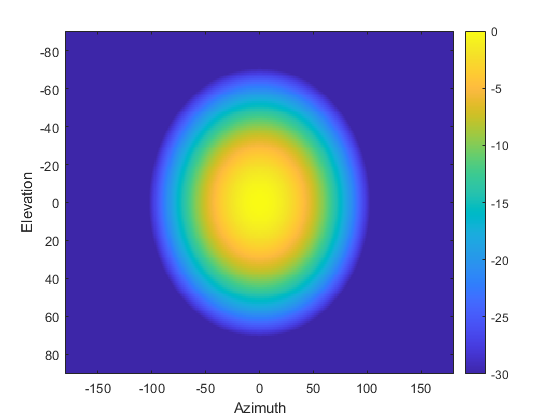

% Azimuth and elevation angles to test
el = (-90:1:90)';
az = (-180:1:180)';

% Elevation and azimuth pattern.  
% Note that the formula in the table is 90-theta.  
% This is the elevation angle, el
AEV = -min(12*(el/elHpbw).^2, SLAv);
AEH = -min(12*(az/azHpbw).^2, Am);

% Create the directivity matrix
D0 = -min(-(AEV + AEH'), Am);

% Plot the un-normalized directivity
imagesc(az,el,D0);
colorbar();
xlabel('Azimuth');
ylabel('Elevation');

## Normalizing the Directivity

The directivity matrix `A0` above is unnormalized.  The actual directivity (in dBi) is of the form:

where `Dscale` is a scale factor.  In linear scale, the directivity is `D=D0*Dscale. ` We can compute this scaling factor `Dscale` using the fact that the directivity must be normalized to one.  Specifically, in linear scale with continuous values:

To do this integration in discrete values, we can recognize that for any function `f(theta,phi) :`

where the constant `scale` is a scaling factor between the continuous integral and the mean on the discrete points and `F` is the matrix of values `F(i,j) = f(theta(i), phi(j))` .  We can find the scale factor by taking `f = 1`:

azRad = deg2rad(az);
elRad = deg2rad(el);
scale = 1/mean(cos(elRad));

We can then compute the scaling factor:

D0avg = mean(db2pow(D0).*cos(elRad), "all")*scale;
Dscale = -pow2db(D0avg);


Then, we normalize the directivity:

D = Dscale + D0;


In the case of the 3GPP pattern, the maximum of the un-normalized density is `max_{ij} D0(i,j)=0. `Therefore, the maximum of the normalized density is:

So, in this case, `Dscale` is also the maximum directivity.  

fprintf(1,'Maximum directivity = %7.2f dBi\n', Dscale);

Maximum directivity =   11.16 dBi


## Plotting the Directivity

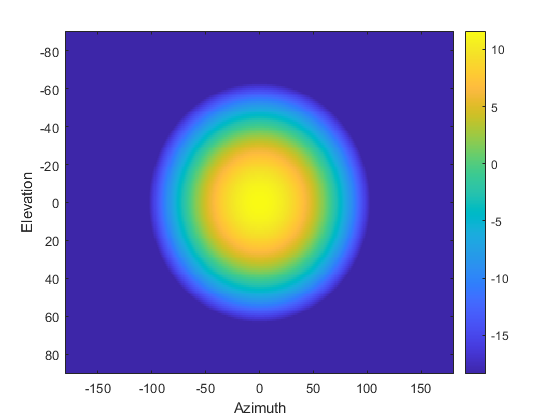

% Plot the normalized directivity
imagesc(az,el,D);
colorbar();
xlabel('Azimuth');
ylabel('Elevation');

## Creating a Custom Antenna Element

Create a custom antenna element with this pattern and then display its pattern.

ant = phased.CustomAntennaElement(...
    "AzimuthAngles", az, "ElevationAngles", el,...
    "MagnitudePattern", D);

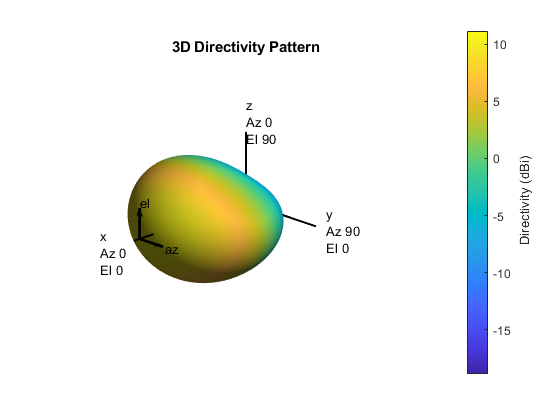

fc = 28e9;
ant.pattern(fc);

## Rotating the Antenna

Suppose we want to aim the antenna at some azimuth angle, `az0,` and elevation angle el0.  Unfortunately, the `CustomAntennaElement` object in MATLAB does not have a `Tilt` parameter to do this.  But, we can create a rotated element by rotating the pattern as follows:

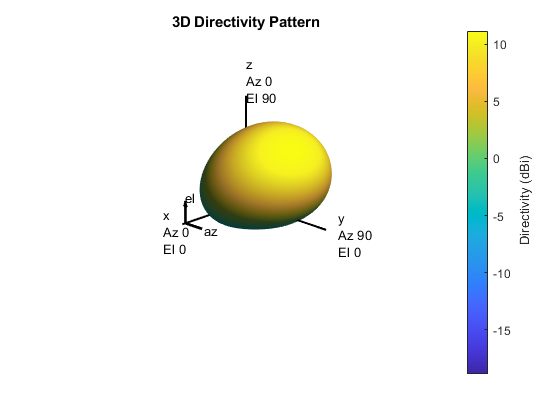

% Angle to rotate the antenna
el0 = 45;
az0 = 80;

% Create the rotation matrix.  Note the negative elevation rotation from
% the right hand rule.
newax = rotz(az0)*roty(-el0);

% Rotate the pattern
Drot = rotpat(D,az,el,newax);

% Create the rotated element
antRot = phased.CustomAntennaElement(...
    "AzimuthAngles", az, "ElevationAngles", el,...
    "MagnitudePattern", Drot);

% Plot the pattern
antRot.pattern(fc);

We can also plot the rotated directivity on 2D.  We have placed a marker at the desired boresight.

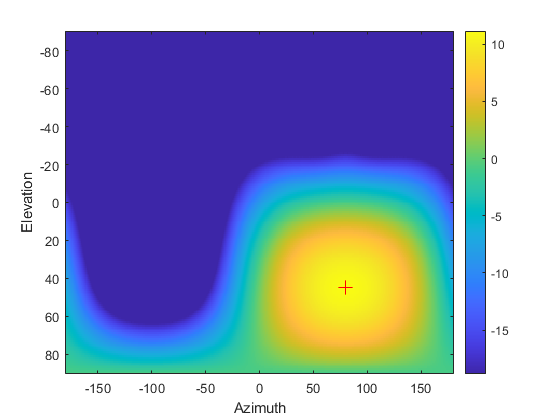

imagesc(az,el,Drot);
colorbar();
hold on;
plot(az0,el0, 'r+', 'MarkerSize',10);
hold off;
xlabel('Azimuth');
ylabel('Elevation');